# Show renders from our lenses

This script allows you to visualize in advance how a scene will render through some or all of our current lenses for a user-selected sensor size. By default it will use all of the lens files in your path, but you can filter for those containing a specific string in their name.

Dependencies: ISET3d-v4, ISETCam, isetlens

D. Cardinal, 2022

Note: For expediency, we have pre-generated several possible variations of scene and sensor size and placed them as HTML files in the previews sub-folder.

## Initialize ISET and Docker

ieInit;
if ~piDockerExists, piDockerConfig; end

## Choose Options

sensorSize =12; % (diagonal in mm)
useScene = 'chessSet'; % one of our default scenes
raysPerPixel = 128;
sensorResolution = 400;
% optionally only render matching lenses
lensNameFilter = "";

fprintf('Lens Inventory using Scene: %s\n', useScene);

Lens Inventory using Scene: chessSet


fprintf('Sensor Size: %d, rayPP %d, resolution %d\n',...
    sensorSize,raysPerPixel,sensorResolution);

Sensor Size: 12, rayPP 128, resolution 400


## Read the selected Scene and add a Light

thisR  = piRecipeDefault('scene name',useScene);

Read 9 materials and 3 textures..


lightName = 'from camera';
ourLight = piLightCreate(lightName,...
    'type','distant',...
    'cameracoordinate', true);
recipeSet(thisR,'lights', ourLight,'add');

## Set render quality

% Set resolution for speed or quality.
thisR.set('film resolution',[sensorResolution sensorResolution]);  % 2 is high res. 0.25 for speed
thisR.set('rays per pixel',raysPerPixel);                      % 128 for high quality

% Pick out a bit of the image to look at.  Middle dimension is up.
% Third dimension is z.  For the chess set we use a from/to that put the ruler in the
% middle.  The in focus is about the pawn or rook.
switch(useScene)
    case 'chessSet'
        thisR.set('from',[0 0.14 -0.7]);     % Get higher and back away than default
        thisR.set('to',  [0.05 -0.07 0.5]);  % Look down default compared to default
    case 'cornell_box'
        %
end
%thisR.set('aperture diameter',1);   % thisR.summarize('all');

## Determine the range of object depths in our scene

Note: Getting depth will use pinhole optics, but we use an omni camera with lenses for the rest.

depthRange = thisR.get('depth range');

Started Docker (status 0): docker  --context render-vista run -d -it  --gpus device=0  --name pbrt-gpu-Windows14136  -v /home/david/iset/iset3d-v4/local/:/iset/iset3d-v4/local/  digitalprodev/pbrt-v4-gpu-ampere-mux-shared bash
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.91
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  36.49
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.88
*** Rendering time for ChessSet:  42.5 sec ***

exr2bin done.

%depthRange = [0.1674, 3.3153];  % Chess set distances in meters

## Create cameras that use each lens

We get a list of all our lenses, then iterate over it creating a camera object using that lens, and render the same scene through each of them.

allLensFiles = lensC.list('quiet', true, 'lensRoot', piRootPath);
if ~isempty(lensNameFilter)
    lensNames = {allLensFiles.name};
    lensIdx = contains(lensNames,lensNameFilter);
    lensFiles = allLensFiles(lensIdx);
else
    lensFiles = allLensFiles;
end
images = []; % our output images
debugOnly = false;
if debugOnly
    lensCount = 2;
else
    lensCount = numel(lensFiles);
end

for ii = 1:lensCount
    lensFileName = lensFiles(ii).name;
    lensFile = fullfile(lensFiles(ii).folder, lensFileName);
    fprintf('Using lens #%d: %s\n',ii, lensFile);
    thisR.camera = piCameraCreate('omni','lensFile',lensFile);
    thisR.set('focal distance',mean(depthRange));
    
    % depending on the film size we'll get
    % different fields of view
    thisR.set('film diagonal',sensorSize);

## Render and display

Using lens #1: B:\iset\iset3d-v4\data\lens\2ElLens.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.05
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.75
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.31
*** Rendering time for ChessSet:  13.2 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\2ElLens.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.57
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.9 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\2ElLens.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.73
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.75
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.63
*** Rendering time for stepfunction:  9.2 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\2ElLens.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed 

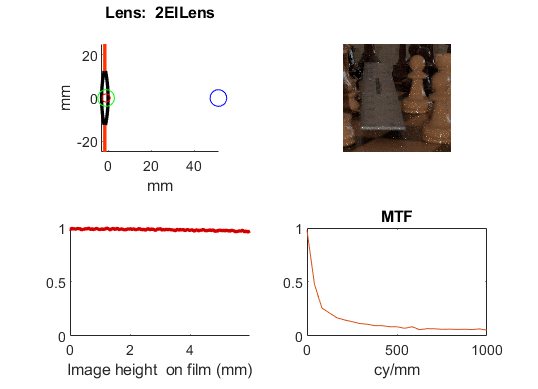

Using lens #2: B:\iset\iset3d-v4\data\lens\2el.XXdeg.100mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.17
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.20
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.10
*** Rendering time for ChessSet:  12.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.48
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.73
*** Rendering time for flatSurface:  9.9 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.70
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.63
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

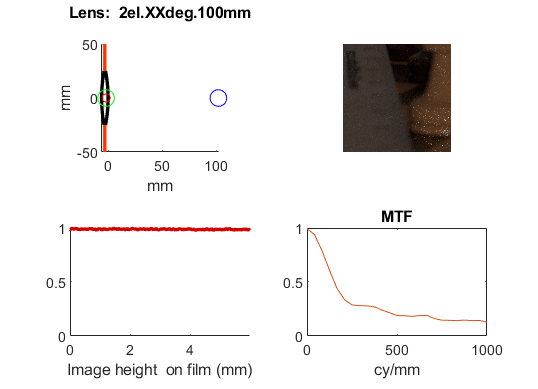

Using lens #3: B:\iset\iset3d-v4\data\lens\2el.XXdeg.12mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.17
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   9.35
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.19
*** Rendering time for ChessSet:  11.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.36
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.64
*** Rendering time for flatSurface:  9.7 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.32
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.73
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

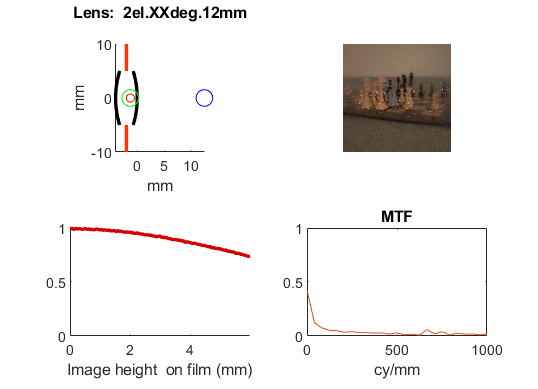

Using lens #4: B:\iset\iset3d-v4\data\lens\2el.XXdeg.50mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.64
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.30
*** Rendering time for ChessSet:  13.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.27
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.73
*** Rendering time for flatSurface:  9.7 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.29
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Win

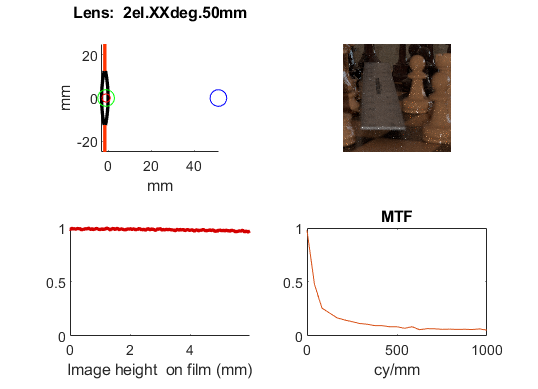

Using lens #5: B:\iset\iset3d-v4\data\lens\2el.XXdeg.6.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.58
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.08
*** Rendering time for ChessSet:  10.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   7.73
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.74
*** Rendering time for flatSurface:  9.2 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   6.88
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  8.3 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Win

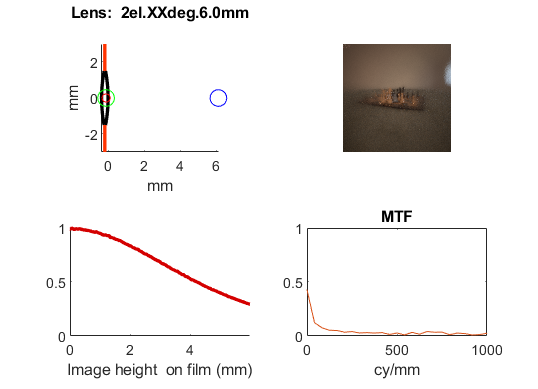

Using lens #6: B:\iset\iset3d-v4\data\lens\dgauss.22deg.100.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  11.47
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.29
*** Rendering time for ChessSet:  13.9 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   9.64
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.74
*** Rendering time for flatSurface:  11.1 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   8.48
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.64
*** Rendering time for stepfunction:  9.8 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

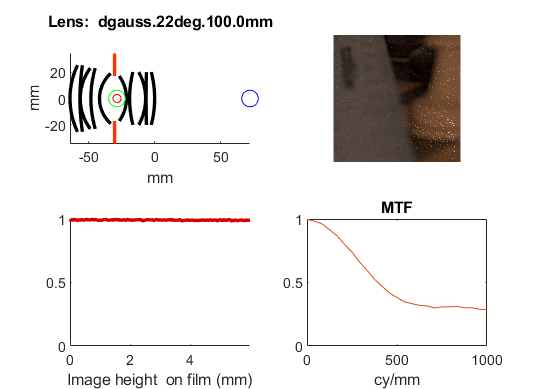

Using lens #7: B:\iset\iset3d-v4\data\lens\dgauss.22deg.12.5mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   9.24
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.99
*** Rendering time for ChessSet:  11.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.91
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  10.2 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   6.86
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.3 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Win

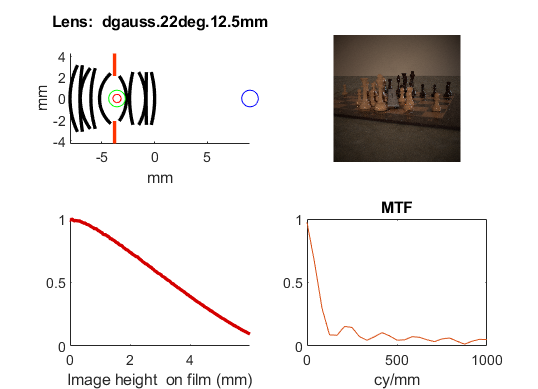

Using lens #8: B:\iset\iset3d-v4\data\lens\dgauss.22deg.3.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   7.84
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.75
*** Rendering time for ChessSet:  9.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.30
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.75
*** Rendering time for flatSurface:  9.7 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   6.97
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  8.4 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Win

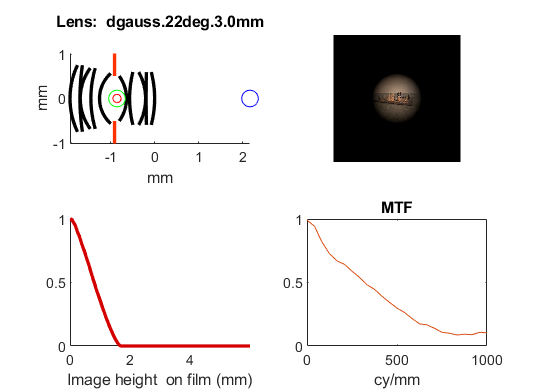

Using lens #9: B:\iset\iset3d-v4\data\lens\dgauss.22deg.50.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.05
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  11.25
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.31
*** Rendering time for ChessSet:  13.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   9.34
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.73
*** Rendering time for flatSurface:  10.8 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   8.38
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  9.8 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

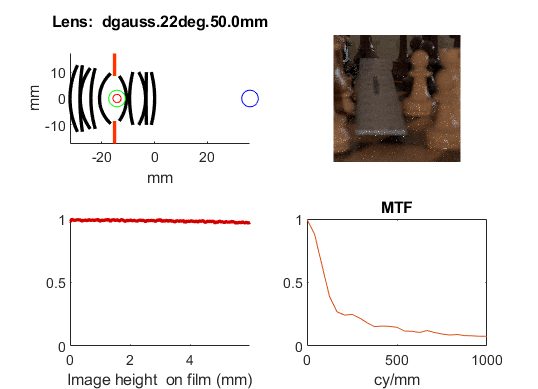

Using lens #10: B:\iset\iset3d-v4\data\lens\dgauss.22deg.6.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.15
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.56
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.08
*** Rendering time for ChessSet:  10.9 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.74
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.68
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.74
*** Rendering time for flatSurface:  10.2 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   6.95
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.4 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

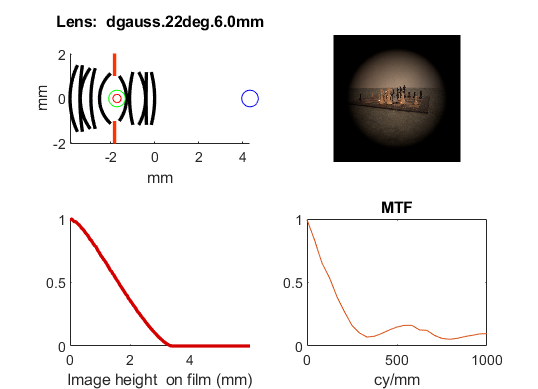

Using lens #11: B:\iset\iset3d-v4\data\lens\dgauss.22deg.6.0mm_v3.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.99
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.98
*** Rendering time for ChessSet:  11.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.80
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.74
*** Rendering time for flatSurface:  10.2 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.74
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   6.87
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.4 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Win

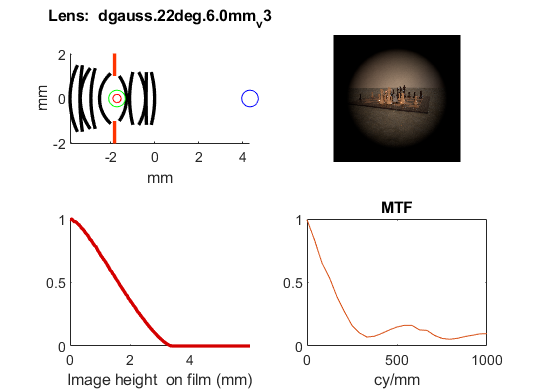

Using lens #12: B:\iset\iset3d-v4\data\lens\endoscope.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Error Rendering: pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?


Status:
     1

Result:
pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?

*** Rendering time for ChessSet:  3.8 sec ***



Using lens #13: B:\iset\iset3d-v4\data\lens\endoscopeFixed.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Error Rendering: pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?


Status:
     1

Result:
pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?

*** Rendering time for ChessSet:  3.9 sec ***



Using lens #14: B:\iset\iset3d-v4\data\lens\fisheye.87deg.100.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.60
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.88
*** Rendering time for ChessSet:  12.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.100.0mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   9.11
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.75
*** Rendering time for flatSurface:  10.5 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.100.0mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   8.03
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  9.5 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.100.0mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfun

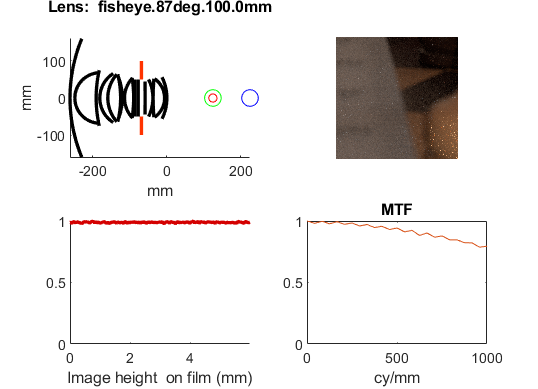

Using lens #15: B:\iset\iset3d-v4\data\lens\fisheye.87deg.12.5mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.04
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.07
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.09
*** Rendering time for ChessSet:  12.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.12.5mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.98
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  10.3 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.12.5mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.93
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.73
*** Rendering time for stepfunction:  9.4 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.12.5mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunc

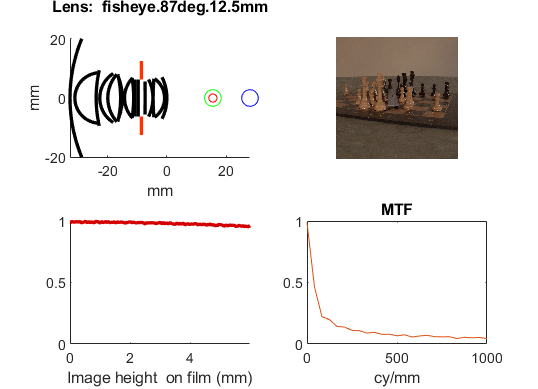

Using lens #16: B:\iset\iset3d-v4\data\lens\fisheye.87deg.3.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.89
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.09
*** Rendering time for ChessSet:  11.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.3.0mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.67
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  10.0 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.3.0mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.08
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  8.5 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.3.0mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunct

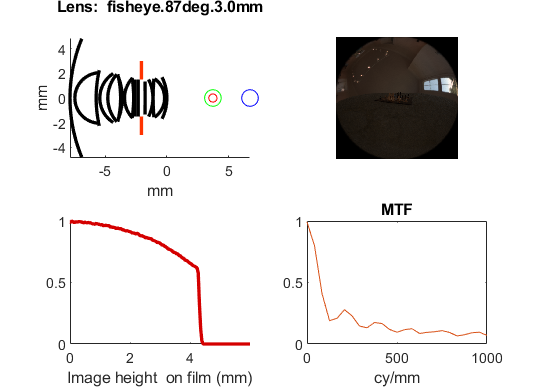

Using lens #17: B:\iset\iset3d-v4\data\lens\fisheye.87deg.50.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.17
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.88
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.09
*** Rendering time for ChessSet:  13.2 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.50.0mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   9.12
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  10.4 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.50.0mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   8.24
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  9.7 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.50.0mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunc

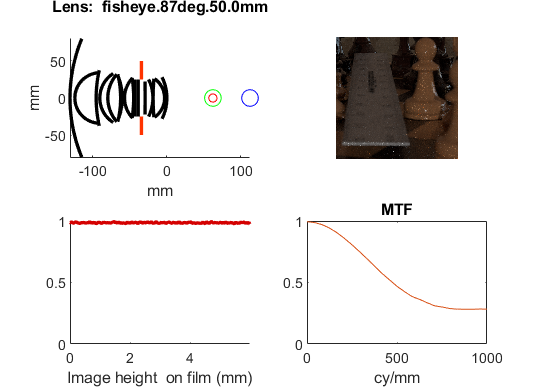

Using lens #18: B:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.68
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.87
*** Rendering time for ChessSet:  10.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.36
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.74
*** Rendering time for flatSurface:  9.8 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.27
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunct

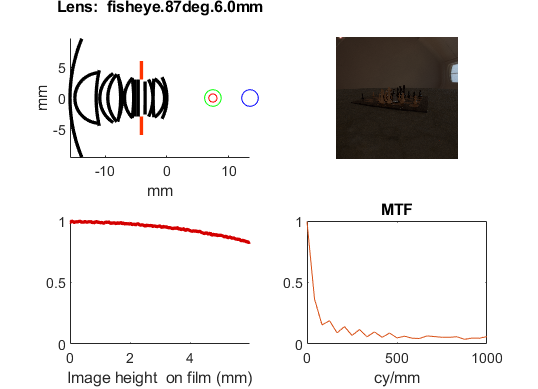

Using lens #19: B:\iset\iset3d-v4\data\lens\gullstrand.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.05
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.99
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.99
*** Rendering time for ChessSet:  11.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\gullstrand.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.36
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.7 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\gullstrand.json


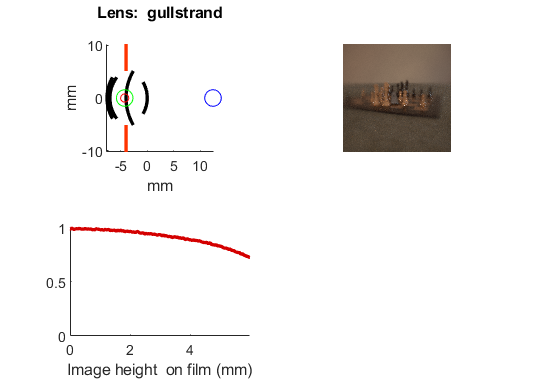

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Error Rendering: pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?


Status:
     1

Result:
pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?

*** Rendering time for stepfunction:  3.4 sec ***



Using lens #20: B:\iset\iset3d-v4\data\lens\microlens.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Error Rendering: pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from scene to film for thick lens approximation. Is aperture stop extremely small?


Status:
     1

Result:
pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from scene to film for thick lens approximation. Is aperture stop extremely small?

*** Rendering time for ChessSet:  3.9 sec ***



Using lens #21: B:\iset\iset3d-v4\data\lens\petzval.12deg.100.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.09
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.19
*** Rendering time for ChessSet:  12.4 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.100.0mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.78
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  10.1 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.100.0mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.72
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.63
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.100.0mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfun

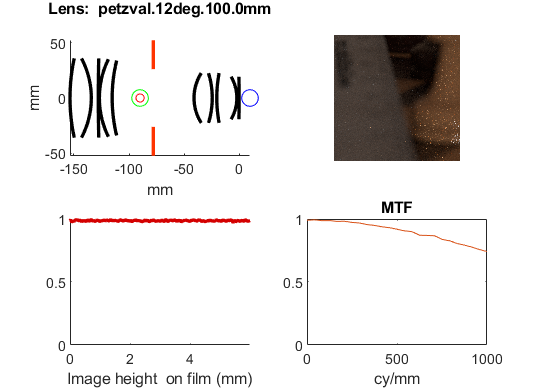

Using lens #22: B:\iset\iset3d-v4\data\lens\petzval.12deg.12.5mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.57
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.87
*** Rendering time for ChessSet:  10.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.12.5mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.56
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.74
*** Rendering time for flatSurface:  10.0 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.12.5mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.61
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.73
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.12.5mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunc

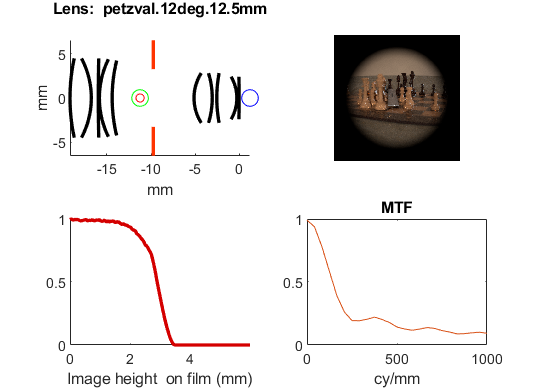

Using lens #23: B:\iset\iset3d-v4\data\lens\petzval.12deg.3.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   7.62
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.76
*** Rendering time for ChessSet:  9.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.3.0mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.27
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.75
*** Rendering time for flatSurface:  9.7 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.3.0mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.61
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.63
*** Rendering time for stepfunction:  8.9 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.3.0mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunct

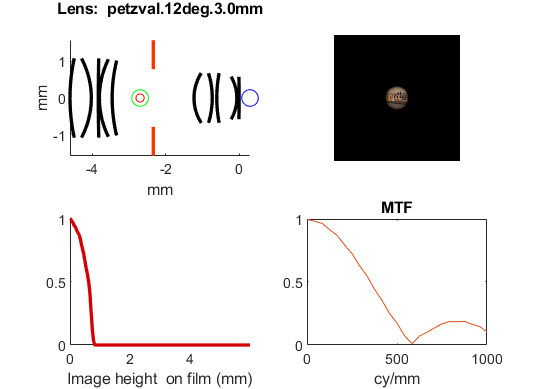

Using lens #24: B:\iset\iset3d-v4\data\lens\petzval.12deg.50.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.41
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.30
*** Rendering time for ChessSet:  12.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.50.0mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.49
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.73
*** Rendering time for flatSurface:  9.9 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.50.0mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.72
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.63
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.50.0mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunc

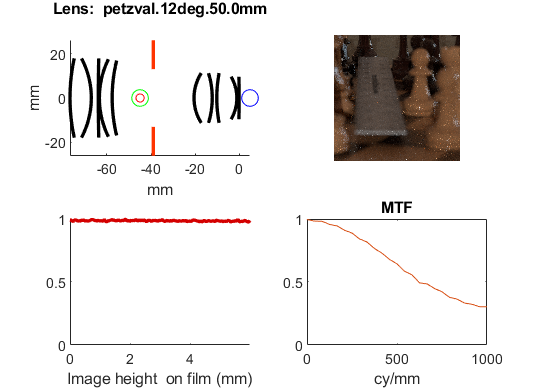

Using lens #25: B:\iset\iset3d-v4\data\lens\petzval.12deg.6.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   7.62
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.77
*** Rendering time for ChessSet:  9.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.6.0mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.45
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.8 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.6.0mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.49
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.63
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\petzval.12deg.6.0mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunct

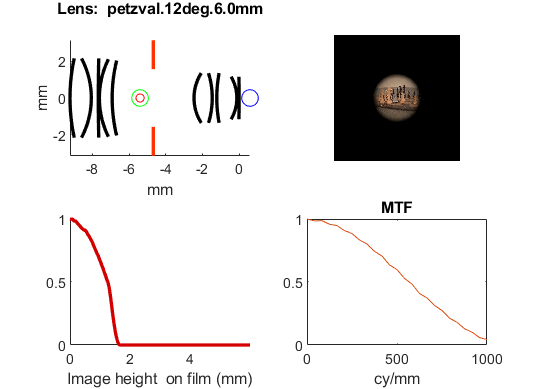

Using lens #26: B:\iset\iset3d-v4\data\lens\pxel4a-frontcamera-filmtoscene-raytransfer.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.05
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Error Rendering: pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Error, lens specification file without a valid surface array "lens/pxel4a-frontcamera-filmtoscene-raytransfer.json".
Error: ChessSet.pbrt:7:0: omni: unable to create camera.


Status:
     1

Result:
pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Error, lens specification file without a valid surface array "lens/pxel4a-frontcamera-filmtoscene-raytransfer.json".
Error: ChessSet.pbrt:7:0: omni: unable to create camera.

*** Rendering time for ChessSet:  3.9 sec ***



Using lens #27: B:\iset\iset3d-v4\data\lens\telephoto.250mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Error Rendering: pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Coefficient must be positive. It looks focusDistance 1  is too short for a given lenses configuration


Status:
     1

Result:
pbrt version 4 (built May  8 2022 at 00:54:47)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Coefficient must be positive. It looks focusDistance 1  is too short for a given lenses configuration

*** Rendering time for ChessSet:  4.0 sec ***



Using lens #28: B:\iset\iset3d-v4\data\lens\tessar.22deg.100.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.94
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.30
*** Rendering time for ChessSet:  13.4 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.72
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   9.26
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.62
*** Rendering time for flatSurface:  10.7 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.81
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  9.3 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Win

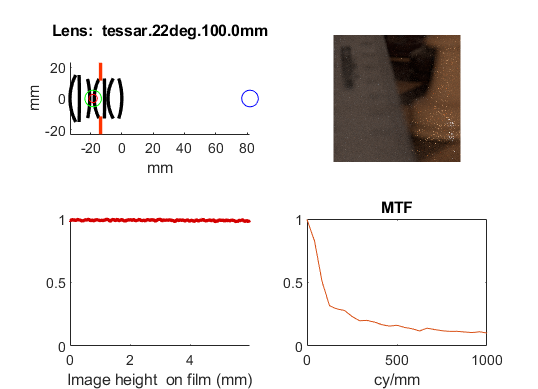

Using lens #29: B:\iset\iset3d-v4\data\lens\tessar.22deg.12.5mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   9.11
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.08
*** Rendering time for ChessSet:  11.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.06
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.4 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   6.75
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.2 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Win

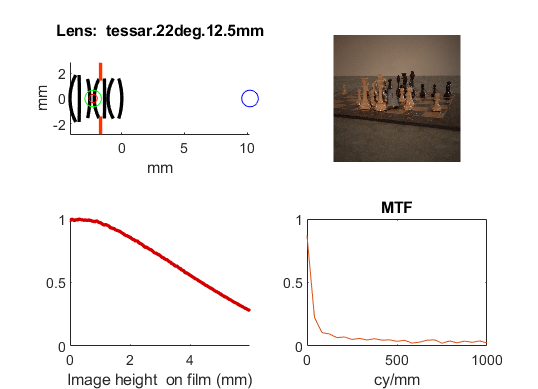

Using lens #30: B:\iset\iset3d-v4\data\lens\tessar.22deg.3.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   7.94
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.87
*** Rendering time for ChessSet:  9.9 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.73
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.35
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.8 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   6.87
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  8.3 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.74
Render: docker --context render-vista exec -i  pbrt-gpu-Win

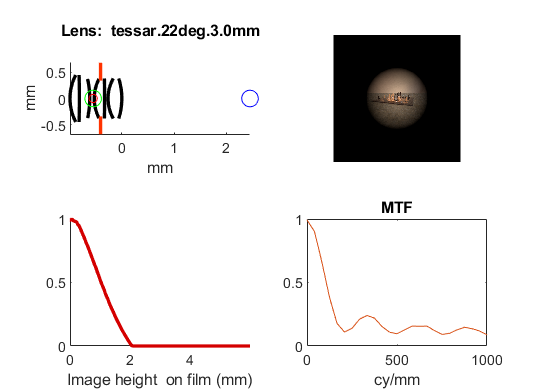

Using lens #31: B:\iset\iset3d-v4\data\lens\tessar.22deg.50.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:  10.94
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.29
*** Rendering time for ChessSet:  13.4 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.74
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.90
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.62
*** Rendering time for flatSurface:  10.3 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.82
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  9.3 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

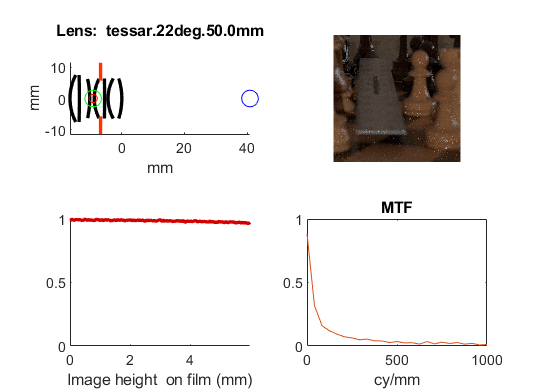

Using lens #32: B:\iset\iset3d-v4\data\lens\tessar.22deg.6.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.90
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.99
*** Rendering time for ChessSet:  11.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.69
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.75
*** Rendering time for flatSurface:  10.1 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   6.86
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.62
*** Rendering time for stepfunction:  8.2 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

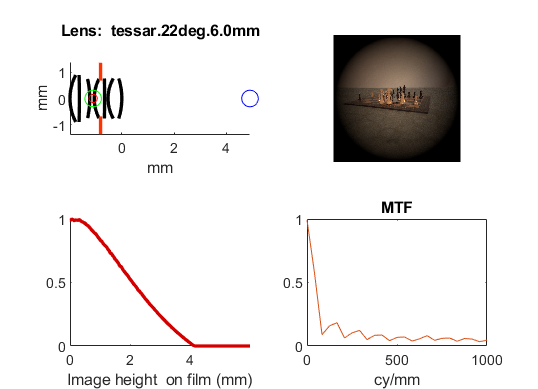

Using lens #33: B:\iset\iset3d-v4\data\lens\wide.40deg.100.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.26
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.09
*** Rendering time for ChessSet:  10.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.74
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.15
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.74
*** Rendering time for flatSurface:  9.7 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.27
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.63
*** Rendering time for stepfunction:  8.6 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

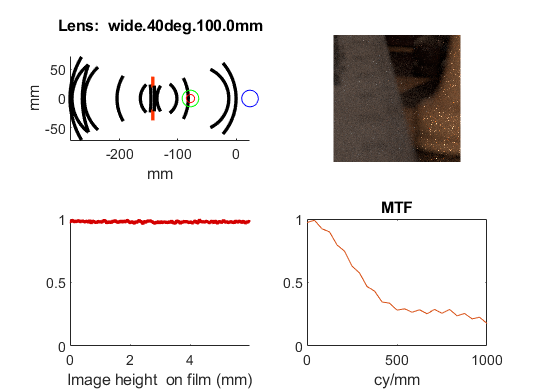

Using lens #34: B:\iset\iset3d-v4\data\lens\wide.40deg.12.5mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.79
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.18
*** Rendering time for ChessSet:  11.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.36
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.7 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.28
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.62
*** Rendering time for stepfunction:  8.6 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

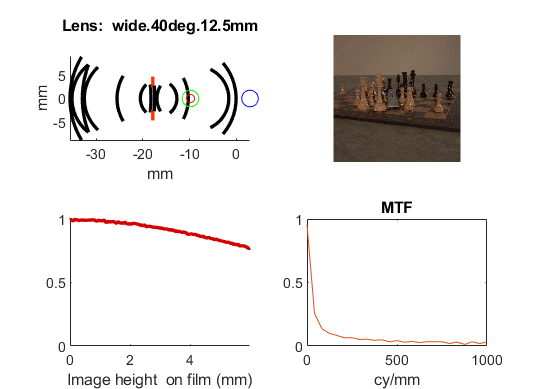

Using lens #35: B:\iset\iset3d-v4\data\lens\wide.40deg.3.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.08
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   7.42
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.97
*** Rendering time for ChessSet:  9.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.14
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.62
*** Rendering time for flatSurface:  9.5 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.30
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Win

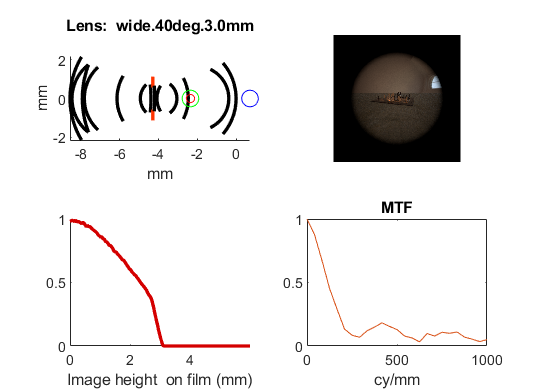

Using lens #36: B:\iset\iset3d-v4\data\lens\wide.40deg.50.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.79
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.98
*** Rendering time for ChessSet:  10.9 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.14
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.5 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.18
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.62
*** Rendering time for stepfunction:  8.5 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

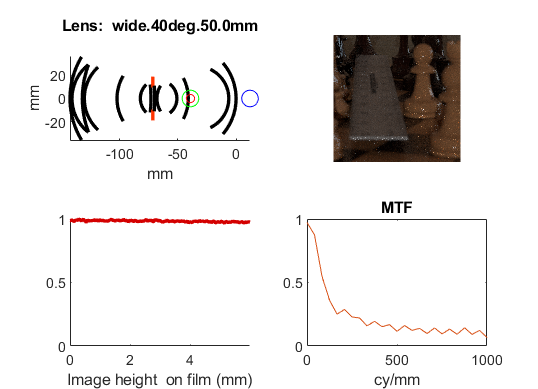

Using lens #37: B:\iset\iset3d-v4\data\lens\wide.40deg.6.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.07
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.69
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.19
*** Rendering time for ChessSet:  11.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.16
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.75
*** Rendering time for flatSurface:  9.6 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.09
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.73
*** Rendering time for stepfunction:  8.5 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

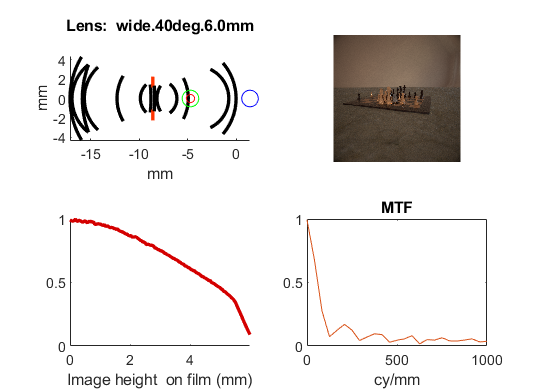

Using lens #38: B:\iset\iset3d-v4\data\lens\wide.56deg.100.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   9.35
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.19
*** Rendering time for ChessSet:  11.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.26
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.64
*** Rendering time for flatSurface:  9.6 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.39
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

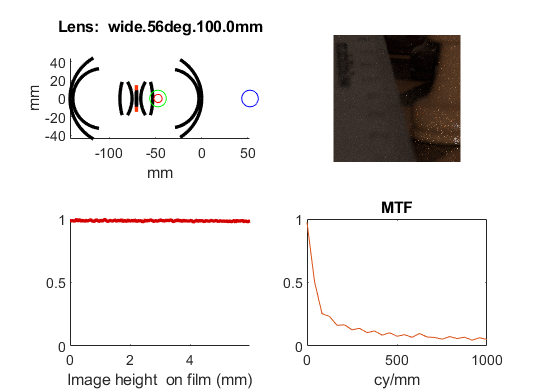

Using lens #39: B:\iset\iset3d-v4\data\lens\wide.56deg.12.5mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.99
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.12
*** Rendering time for ChessSet:  11.2 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.27
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.6 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.74
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.08
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  8.6 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.73
Render: docker --context render-vista exec -i  pbrt-gpu-Win

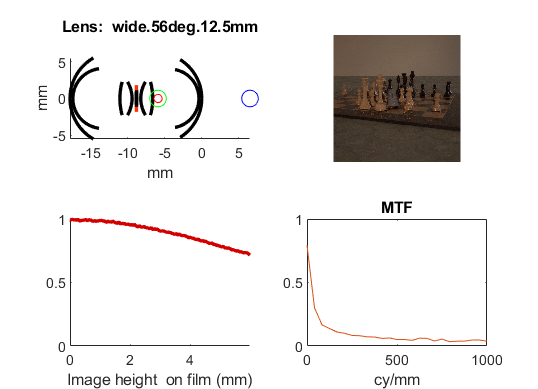

Using lens #40: B:\iset\iset3d-v4\data\lens\wide.56deg.3.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.50
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   7.93
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.09
*** Rendering time for ChessSet:  10.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.05
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.4 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.18
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.6 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

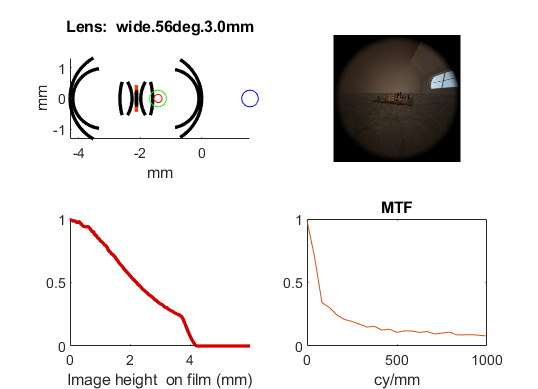

Using lens #41: B:\iset\iset3d-v4\data\lens\wide.56deg.50.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   9.87
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.98
*** Rendering time for ChessSet:  12.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.72
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.14
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.75
*** Rendering time for flatSurface:  9.7 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.10
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.75
*** Rendering time for stepfunction:  8.5 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Win

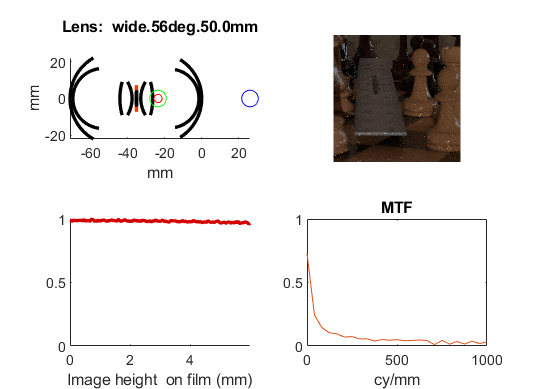

Using lens #42: B:\iset\iset3d-v4\data\lens\wide.56deg.6.0mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.45
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.07
*** Rendering time for ChessSet:  10.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.64
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.36
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.73
*** Rendering time for flatSurface:  9.8 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.17
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.6 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Win

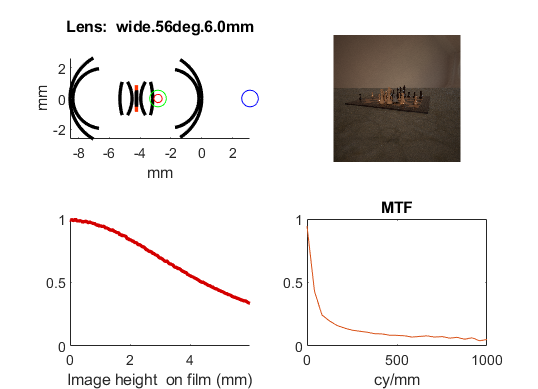

Using lens #43: B:\iset\iset3d-v4\data\lens\wide.56deg.6.0mm_v3.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.70
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.87
*** Rendering time for ChessSet:  10.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.63
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.46
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.63
*** Rendering time for flatSurface:  9.8 sec ***

exr2bin done.

Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.74
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.19
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.76
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.90
Render: docker --context render-vista exec -i  pbrt-gpu-Win

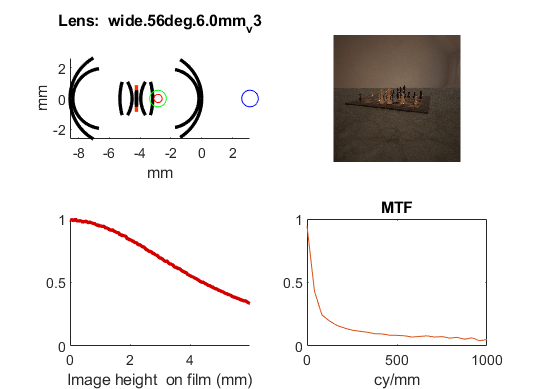

Using lens #44: B:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.06
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   8.80
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/b/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.19
*** Rendering time for ChessSet:  11.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


Read 2 materials and 0 textures..
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/flatSurface/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/
Pushed scene to remote in:   0.74
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/flatSurface && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/flatSurface.exr flatSurface.pbrt"
Successfuly rendered remotely in:   8.35
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/flatSurface/renderings/ /mnt/b/iset/iset3d-v4/local/flatSurface/renderings
Retrieved output in:   0.74
*** Rendering time for flatSurface:  9.9 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/
Pushed scene to remote in:   0.62
Render: docker --context render-vista exec -i  pbrt-gpu-Windows14136 sh -c "cd /iset/iset3d-v4/local/stepfunction && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/stepfunction.exr stepfunction.pbrt"
Successfuly rendered remotely in:   7.40
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunction/renderings/ /mnt/b/iset/iset3d-v4/local/stepfunction/renderings
Retrieved output in:   0.74
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Decoding lens parameters from lens file name B:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json
Read 0 materials and 0 textures.
 Rsync Put: wsl rsync -r -t /mnt/b/iset/iset3d-v4/local/stepfunction/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/stepfunctio

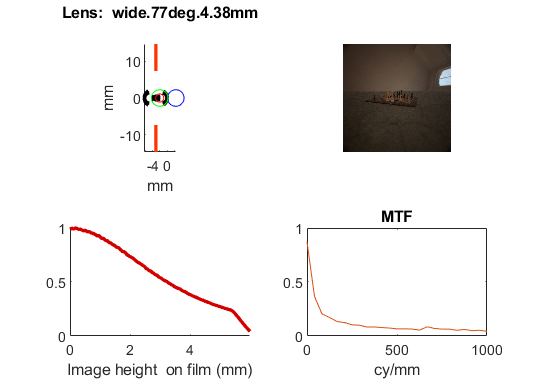

    piWrite(thisR);
    
    try
        oi = piRender(thisR,'render type',{'radiance', 'depth'});
        oi = oiSet(oi,'name',sprintf('Lens: %s  and %d mm sensor',...
            lensFileName, sensorSize));
        % get a viewable version of our optical image:
        img = oiShowImage(oi,-1);
        
        % Load our lens so we can view it
        lenses{ii} = lensC('filename', lensFile);
        
        % Set some headers per lens
        %fprintf('----------------------------\n');
        %fprintf('Rendered using: %s, with focal length: %05.1f',lensFileName,lenses{ii}.focalLength);
        
        % Draw a diagram of our lens into a subplot
        [~,fHdl] = lenses{ii}.draw([2,2,1]);
        
        images{ii} = img; % for creating a montage at the end of the script
        
        % show sample output in our subplot
        subplot(2,2,2);
        imshow(img,'Border','tight');
        
        % plot relative illuminance (into a subplot)
        piRelativeIlluminance("lensfile",lensFile,"figure",[2,2,3],...
            'sensorSize',sensorSize, 'focalDistance', thisR.get('focal distance'),...
            'pixelSamples', 2400); % try to reduce noise

        % plot MTF
        %filmwidth_mm=0.01;
        filmwidth_mm=.01;
        [MTF, ~, ~] = piCalculateMTF('camera',thisR.camera,...
            'distances',depthRange * 1000,...
            'resolution',2000,'rays',1000,...
            'filmwidth', sensorSize/1000, ...
            'quiet',true);
        subplot(224);
        plot(MTF.cyclespermilimeter,MTF.MTF);
        xlabel('cy/mm');
        ylim([0 1]);
        xlim([0 1000]);
        title('MTF');

        % set plot attributes
        set(gcf,'Name',lensFileName,'MenuBar','none','ToolBar','none');

        drawnow; %doesn't seem to help, but who knows?
        % footer if using headers
        %fprintf('----------------------------\n');

    catch
        warning('Lens: %s failed to render.\n', lensFile);
    end
    
end

## Show a Captioned Montage for Reference

For filename captions to be legible we need to make sure we have enough room

minTileSize = 400; thumbnailSize = 400;
boxSize = max(minTileSize, sensorResolution);
textPosition = [10 10; boxSize-30 boxSize-30];
for ii = 1:numel(images)
    if minTileSize > sensorResolution && ~isempty(images{ii})
        imagesR{ii} = imresize(images{ii},[boxSize boxSize]);
    else
        imagesR{ii} = images{ii};
    end
    imagesC{ii} = insertText(imagesR{ii}, textPosition, lensFiles(ii).name, ...
        'FontSize', 36); %#ok<*SAGROW>
end
figure; % new figure below 
fprintf('Lens Inventory using Scene: %s\n', useScene);

Lens Inventory using Scene: chessSet


fprintf('Sensor Size: %d, rayPP %d, resolution %d\n',...
    sensorSize,raysPerPixel,sensorResolution);

Sensor Size: 12, rayPP 128, resolution 400


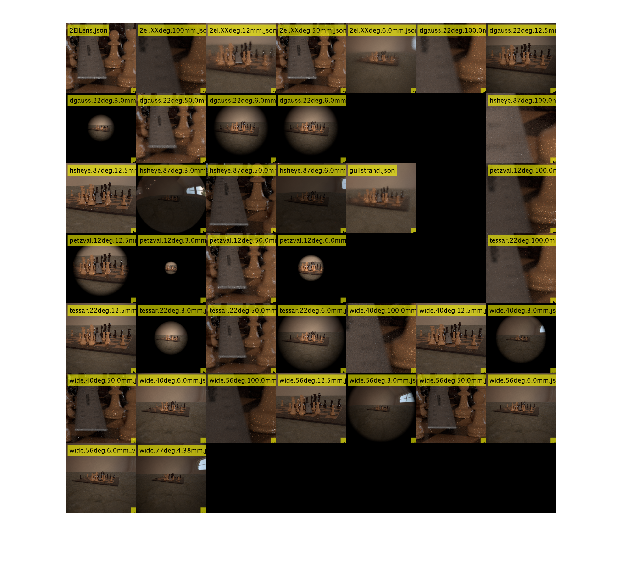

montage(imagesC,'ThumbnailSize',[thumbnailSize thumbnailSize]);